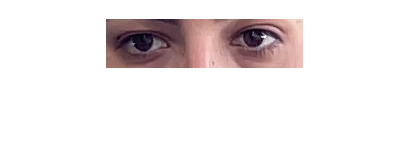

f = imread("/Users/shayanaimi/Desktop/test3.jpg");

%object detection with computer vision toolbox

detector = vision.CascadeObjectDetector('ClassificationModel','EyePairBig');
bbox = detector(f);

eyepairindex = height(bbox);

eyes = imcrop(f, bbox(eyepairindex, :));
imshow(eyes)

eyes_distance = bbox(eyepairindex, 3)

eyes_distance = 196

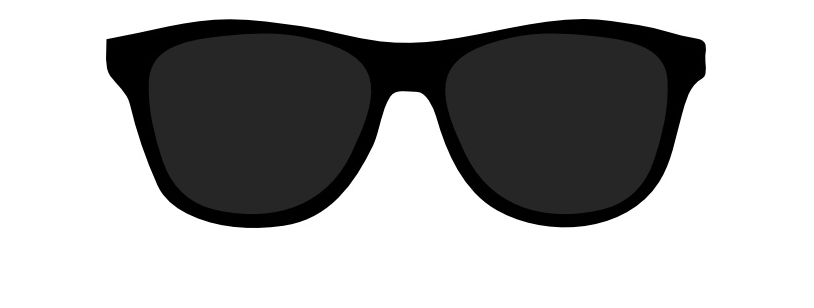

sunglasses = imread("/Users/shayanaimi/Desktop/sunglasses.jpg");
imshow(sunglasses)

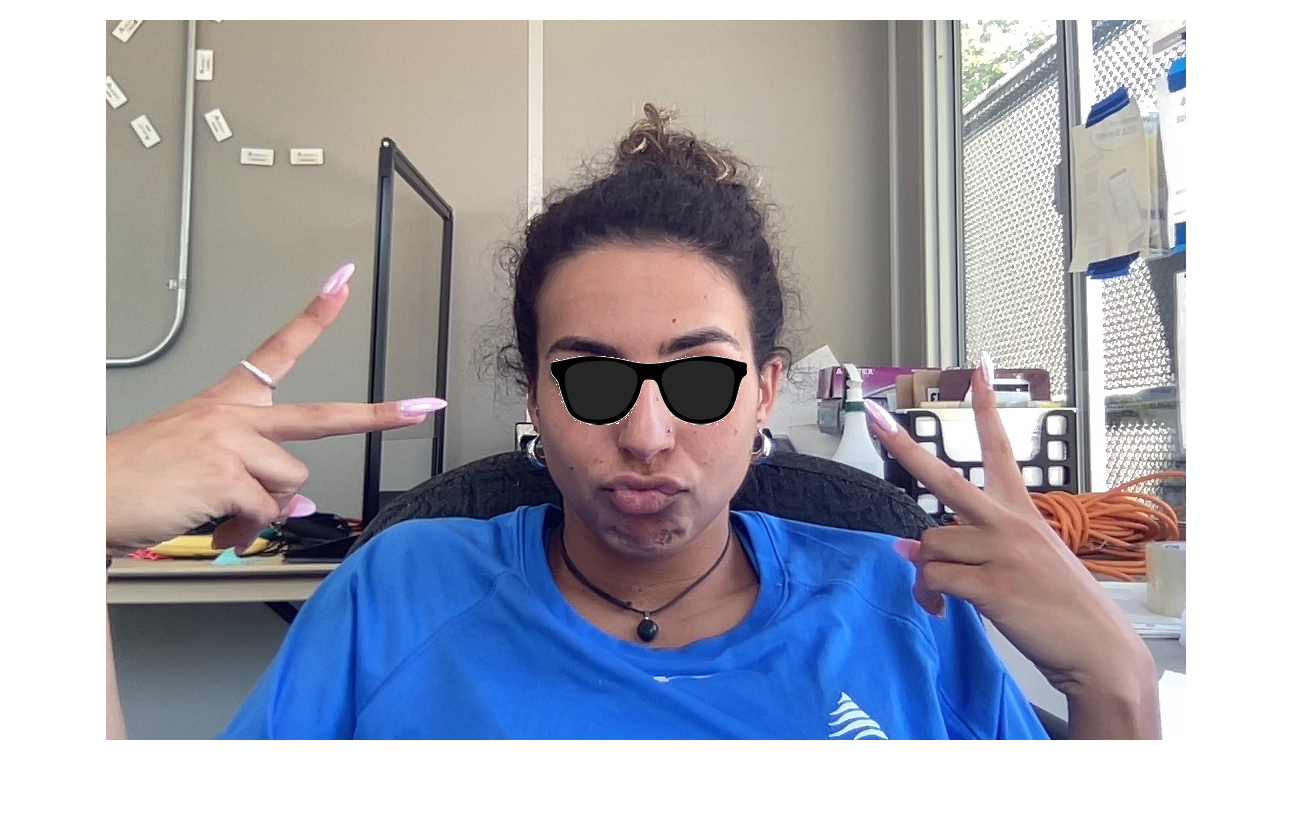

scale = double(eyes_distance / size(sunglasses, 2)); %scale the sticker
scaled_glasses = imresize(sunglasses, scale);


%paste sticker onto original image
for i=1:size(scaled_glasses, 1)
    for j=1:size(scaled_glasses, 2)
        %filter out background
        if scaled_glasses(i, j, 1) == 255 & scaled_glasses(i, j, 2) == 255 & scaled_glasses(i, j, 3) == 255
            continue
        end
        gR = scaled_glasses(i, j, 1);
        gG = scaled_glasses(i, j, 2);
        gB = scaled_glasses(i, j, 3);
        f(i + bbox(eyepairindex, 2), j + bbox(eyepairindex, 1), 1) = gR;
        f(i + bbox(eyepairindex, 2), j + bbox(eyepairindex, 1), 2) = gG;
        f(i + bbox(eyepairindex, 2), j + bbox(eyepairindex, 1), 3) = gB;
    end
end

imshow(f)

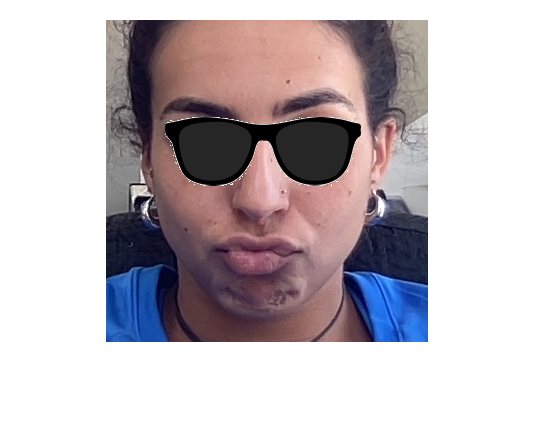

%Alien mask on face - everything repeats

detector = vision.CascadeObjectDetector('ClassificationModel','FrontalFaceCART');
bbox = detector(f);
face = imcrop(f, bbox(1, :));
imshow(face)

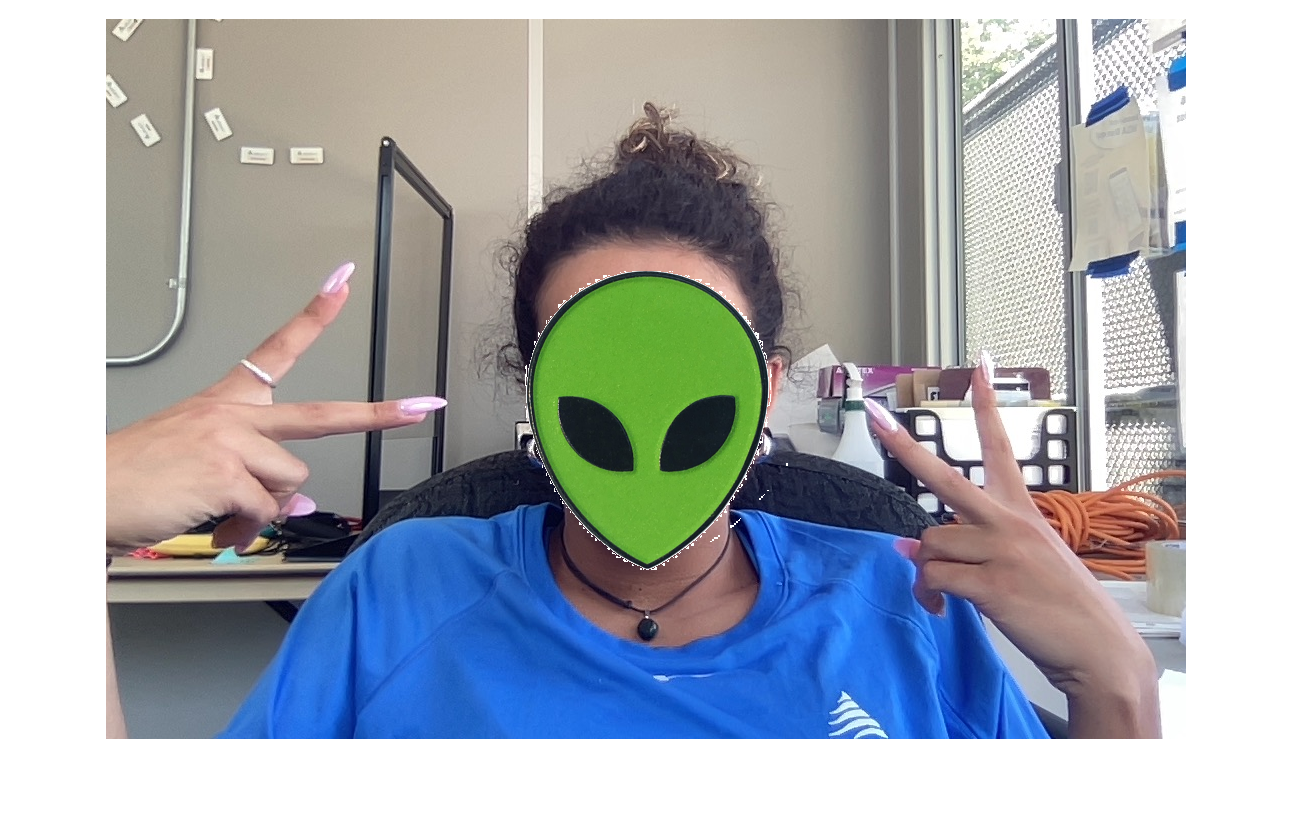


face_width = bbox(1, 3);
alien = imread("/Users/shayanaimi/Desktop/alien.jpg");

scale = double(face_width / size(alien, 2));
scaled_alien = imresize(alien, scale);

for i=1:size(scaled_alien, 1)
    for j=1:size(scaled_alien, 2)
        if scaled_alien(i, j, 1) == 255 & scaled_alien(i, j, 2) == 255 & scaled_alien(i, j, 3) == 255
            continue
        end
        gR = scaled_alien(i, j, 1);
        gG = scaled_alien(i, j, 2);
        gB = scaled_alien(i, j, 3);
        f(i + bbox(1, 2), j + bbox(1, 1), 1) = gR;
        f(i + bbox(1, 2), j + bbox(1, 1), 2) = gG;
        f(i + bbox(1, 2), j + bbox(1, 1), 3) = gB;
    end
end
imshow(f)